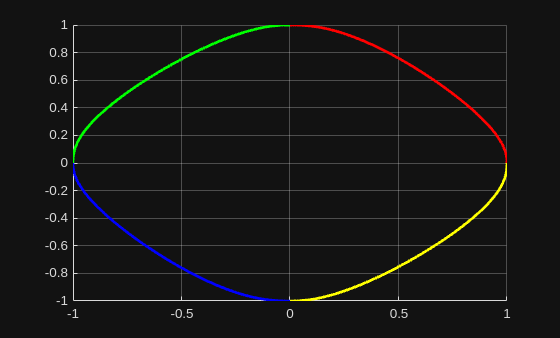

px = [1 0 -1 0]; %cos
py = [0 1 0 -1]; %sin
p = [px;py];

dpx = [0 -1 0 1]; %-sin
dpy = [1 0 -1 0]; %cos
dp = [dpx;dpy];

ddpx = [-1 0 1 0]; %-cos
ddpy = [0 -1 0 1]; %-sin
ddp = [ddpx;ddpy];

f = PathPlanning(p,dp,ddp);

s = 0:0.01:1;
f_ = zeros(2,length(p),length(s));
for i = 1:length(s)
    f_(:,:,i) = f(s(i));
end

x1 = f_(1,1,:);
y1 = f_(2,1,:);

x2 = f_(1,2,:);
y2 = f_(2,2,:);

x3 = f_(1,3,:);
y3 = f_(2,3,:);

x4 = f_(1,4,:);
y4 = f_(2,4,:);
hold on
plot(x1(:),y1(:),'Color','r','LineWidth', 2)
plot(x2(:),y2(:),'Color','g','LineWidth', 2)
plot(x3(:),y3(:),'Color','b','LineWidth', 2)
plot(x4(:),y4(:),'Color','y','LineWidth', 2)
grid on